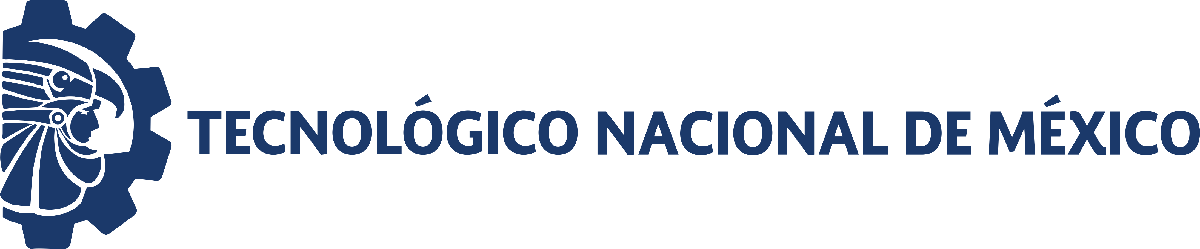                                 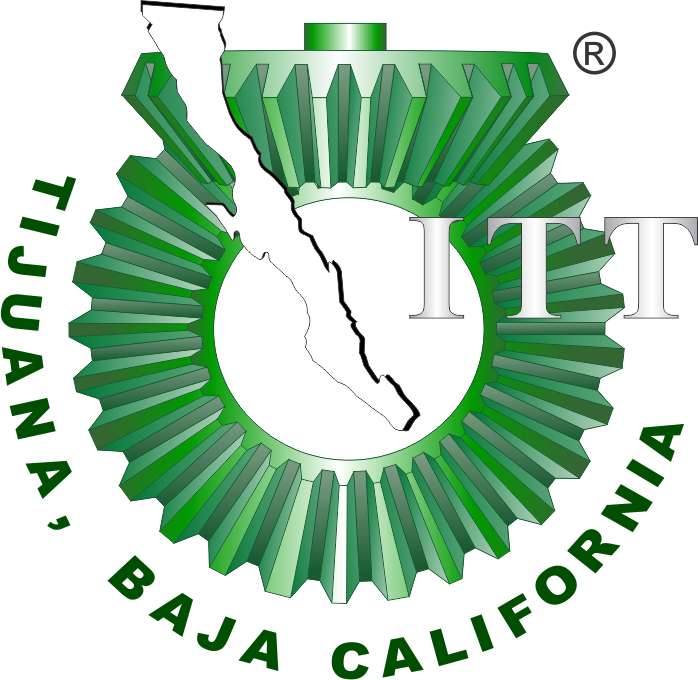

# Práctica 4: Sistema Endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[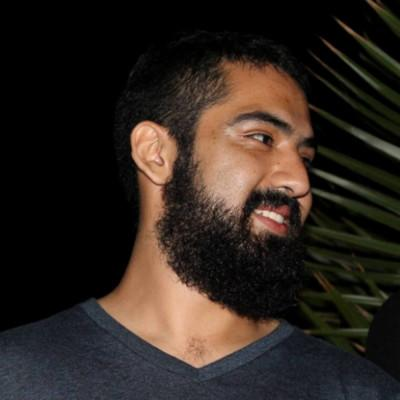]

Nombre del alumno: Dino Seañez Victor Silvano

Número de control: 20211964

Correo institucional: l20211964@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'Sistema';
open_system(file);
parameter.StopTime = '15';
parameter.Solver = 'ode15s';
parameter.MaxStep ='1E-3';
x = sim(file,parameter);

%set_param('Sistema/Ve(t)','VectorFormat','1-D array')

## Respuesta del sistema

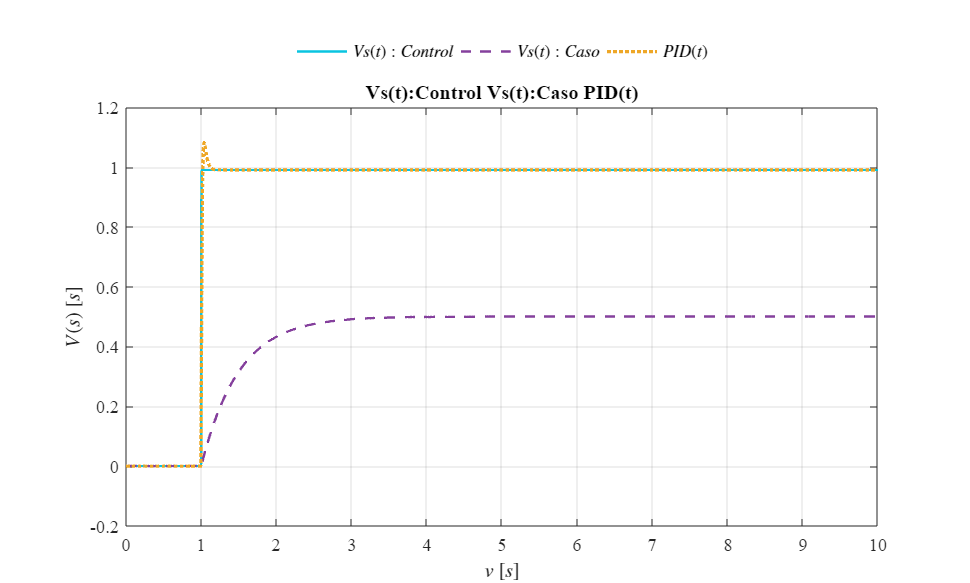

plotsignals(x.t,x.Vs1,x.Vs5,x.PID)

## Respuesta del sistema

function plotsignals(t,VsControl,VsCaso,PID)

    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,25,15])
    set(gca,'FontName','Times New Roman','FontSize',11)

    hold on; grid on; box on;

    powerrangers = [10,196,224;
                    133,64,157;
                    238,167,39]/255;

    % --------- ÚNICA GRÁFICA ----------
    P = plot(t,VsControl,'-',...
             t, VsCaso ,'--',...
             t,PID,':','LineWidth',1.5);

    % Colores
    set(P(1),'Color',powerrangers(1,:))
    set(P(2),'Color',powerrangers(2,:))
    set(P(3),'Color',powerrangers(3,:),'LineWidth',2)

    L = legend('$Vs(t):Control$','$Vs(t):Caso$','$PID(t)$');
    set(L,'Interpreter','Latex','FontSize',10,...
        'location','NorthOutside','box','off','Orientation','Horizontal')

    xlabel('$v$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$V(s)$ $[s]$','Interpreter','Latex','FontSize',11)

    xlim([0,10]); xticks(0:1:10);
    ylim([-0.2,1.2]); yticks(-0.2:0.2:1.2)

    title("Vs(t):Control Vs(t):Caso PID(t)",'FontSize',10);

    set(gca,'FontName','Times New Roman','FontSize',11)

    exportgraphics(gcf,'Endocrino.pdf','ContentType','vector')

end